syms t_c phi_25 MDD Cl MDD_eff phi_min M_crit M_cruise

Km = 1.05;

% MDD = 0.78;
% Cl = 0;
M_desired = 0.75

M_desired = 0.7500


airfoils = {'64012','64015','64009','0009','0012'}

airfoils = 1×5 cell array
    {'64012'}    {'64015'}    {'64009'}    {'0009'}    {'0012'}


colors = {'red','green','blue','magenta','cyan'}

colors = 1×5 cell array
    {'red'}    {'green'}    {'blue'}    {'magenta'}    {'cyan'}


mcrit_airfoils = [.74 .7 .78 .76 .725];


phi_min(M_crit,M_cruise) = acosd((M_crit/M_cruise)^2);
phi_min_airfoils = double(phi_min(mcrit_airfoils,M_desired))

phi_min_airfoils =   13.2170 + 0.0000i  29.4120 + 0.0000i   0.0000 +22.9918i   0.0000 +13.2464i  20.8614 + 0.0000i



MDD_eff = MDD * sqrt(cosd(phi_25));
t_c(MDD,Cl,phi_25) = 0.3*cosd(phi_25) * (( ((1 - ( (5+(MDD_eff^2)) / (5 + (Km-((0.25*Cl)^2)) ) )^(3.5)) * ((sqrt(1-(MDD_eff^2)))/(MDD_eff^2)) ))^(2/3));

simplify(t_c)

$$ans(MDD, Cl, phi\_25) = \frac{3\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\left(-\frac{\left({\left(-\frac{\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\mathrm{MDD}}^{2}+5}{\frac{{\mathrm{Cl}}^{2}}{16}-\frac{121}{20}}\right)}^{7/2}-1\right)\,\sqrt{1-{\mathrm{MDD}}^{2}\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}}{{\mathrm{MDD}}^{2}\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}\right)}^{2/3}}{10}$$



figure
hold on 
t_c_func(phi_25) = subs(t_c,[MDD,Cl],[M_desired,0.435])

$$t\_c\_func(phi\_25) = \frac{3\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)\,{\left(-\frac{16\,\left({\left(\frac{360000\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}{3864431}+\frac{3200000}{3864431}\right)}^{7/2}-1\right)\,\sqrt{1-\frac{9\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}{16}}}{9\,\cos\left(\frac{\pi \,\varphi_{25}}{180}\right)}\right)}^{2/3}}{10}$$

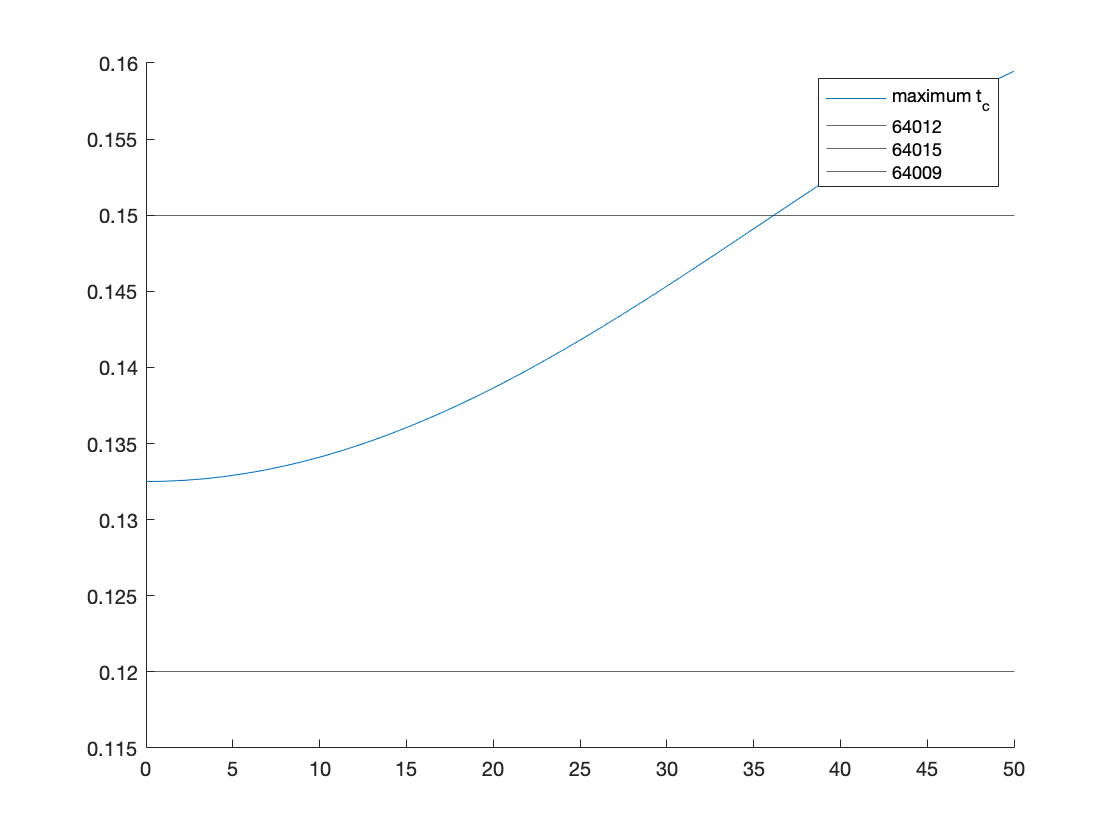


fplot(t_c_func,[0 50])

% for i = 1:length(phi_min_airfoils)
%     xline(phi_min_airfoils(i),'color',colors{i})
% end

yline(.09)
yline(.12)
yline(.15)
ylim([.115 .16])


legend("maximum t_c",'64012','64015','64009','0009','0012')


% fcn = subs(t_c,[Cl,phi_25],[.33,27.4549])

double(t_c(.75,.435,27.4549))

ans = 0.1435


% fsolve(@(x) double(t_c(x,.435,27.5)) - .12 , .6)
%
% double(solve(t_c_func == 0.12))



% fsurf(t_c,[0 1 0 50])
% fsurf(t_c)


